# 1. Read Image & Convert to HSV


% -- CLEAR WORKSPACE --
clear; clc; close all;

% -- READ IMAGE --
img = imread('Image3.jpg');  % Adjust the file name/path as needed.

% Convert to HSV. 
% Note: In MATLAB, Hue, Saturation, and Value are each in the range [0, 1].
imgHSV = rgb2hsv(img);


## 2. Define Color Ranges in HSV



% Each color range is specified as [minH, maxH; minS, maxS; minV, maxV],
% where H, S, V are in the range [0..1].
% Example placeholders (these likely need tweaking!):
colorRanges.red   = [0.00, 0.03;  0.4, 1.0;  0.4, 1.0];  % ~ 0-0.03 in Hue
% Often red can wrap around near Hue=1.0, so you may need a second red range.

colorRanges.green = [0.20, 0.40;  0.3, 1.0;  0.3, 1.0];  
colorRanges.blue  = [0.55, 0.75;  0.3, 1.0;  0.3, 1.0];  
colorRanges.white = [0.00, 1.00;  0.00, 0.2;  0.80, 1.0];  % near white => low S, high V


## 3. Detect the Large Black Circle

    % 1. Resize image if larger than 720x480
    [origH, origW, ~] = size(img);
    maxW = 720;
    maxH = 480;
    
    if origW > maxW || origH > maxH
        scale = min(maxW/origW, maxH/origH);
        img = imresize(img, scale);
        fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
            origH, origW, size(img,1), size(img,2));
    end

Image resized from (3472, 4624) to (481, 640)


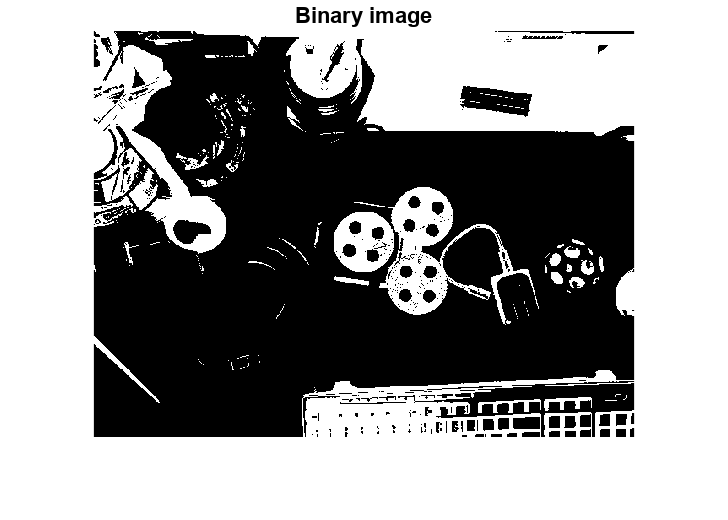

    
    % 2. Convert to grayscale
    grayImg = rgb2gray(img);
    
    % 3. Threshold to get a binary image
    %    We'll invert so dark regions become white in binImg.
    level = 0.3;  % manual threshold (tweak as needed)
    binImg = imbinarize(grayImg, level);
    binImg = ~binImg;  % invert => dark hub is bright/white in binImg
    
    % 4. Show the inverted binary image
    figure; imshow(binImg);
    title('Binary image');

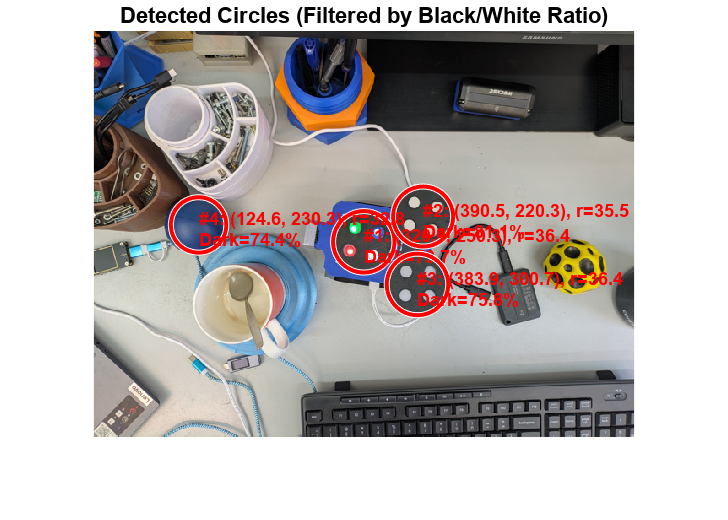

Circle 1 => Ctr=(320.3,250.3), R=36.4, Metric=0.824, DarkFr=0.80
Circle 2 => Ctr=(390.5,220.3), R=35.5, Metric=0.572, DarkFr=0.81
Circle 3 => Ctr=(383.9,300.7), R=36.4, Metric=0.333, DarkFr=0.76


Circle 4 => Ctr=(124.6,230.3), R=32.8, Metric=0.326, DarkFr=0.74


Circle 5 => Filtered out (darkFraction=0.91)


   
    % 5. Detect ALL circles 
    %    The range [15 25] might be for a small circle in your resized image.
    %    'ObjectPolarity','bright' => we inverted so circle is "bright."
    [centers, radii, metric] = imfindcircles(binImg, [15 55], ...
        'ObjectPolarity','bright', 'Sensitivity',0.7);
    
    % 6. Show original image & hold on for drawing
    figure; imshow(img); hold on;
    title('Detected Circles (Filtered by Black/White Ratio)');
    
    if isempty(centers)
        fprintf('No circles found!\n');
        return;
    end
    
    % 7. For each circle, measure how much of it is "white" in binImg
    for i = 1:length(radii)
        c = centers(i, :);   % [x, y] center
        r = radii(i);
        
        % Create a mask of pixels within this circle
        [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
        distSq = (X - c(1)).^2 + (Y - c(2)).^2;
        circleMask = distSq <= (r^2);
        
        % Because binImg == 1 => "dark area" in original
        % Count how many pixels in this circle area are 'on' (i.e., 1)
        whiteCount = sum(binImg(circleMask), 'all');
        
        % The total pixel area of the circle in discrete space:
        circleArea = sum(circleMask(:));
        
        % The fraction of the circle that’s “dark” in the original
        darkFraction = whiteCount / circleArea;
        
        % Alternatively, “lightFraction” = 1 - darkFraction
        % if you want to measure the bright portion from the original.
        
        % Let's define a simple threshold: we keep circles 
        % whose darkFraction is at least 0.70 but no more than 0.85.
        if darkFraction >= 0.70 && darkFraction <= 0.85
            % This circle meets the “darkness” criteria for a hub
            viscircles(c, r, 'Color','r');  % draw in red
            textStr = sprintf('#%d: (%.1f, %.1f), r=%.1f\nDark=%.1f%%', ...
                i, c(1), c(2), r, darkFraction*100);
            text(c(1), c(2)+5, textStr, ...
                'Color','r', 'FontWeight','bold', 'FontSize',9);
            
            fprintf('Circle %d => Ctr=(%.1f,%.1f), R=%.1f, Metric=%.3f, DarkFr=%.2f\n',...
                i, c(1), c(2), r, metric(i), darkFraction);
        else
            % If you want to see the circles that fail, draw them in a different color:
            % (uncomment if you want to visualize them)
            % viscircles(c, r, 'Color','b');
            % text(c(1), c(2)+5, sprintf('Fail [%.1f%%]', darkFraction*100), ...
            %     'Color','b','FontWeight','bold','FontSize',9);
            
            fprintf('Circle %d => Filtered out (darkFraction=%.2f)\n', i, darkFraction);
        end
    end

## 4. Detect Hubs and the internal leds

% 1. Resize image if larger than 720x480
[origH, origW, ~] = size(img);
maxW = 720;
maxH = 480;

if origW > maxW || origH > maxH
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

Image resized from (481, 640) to (480, 639)


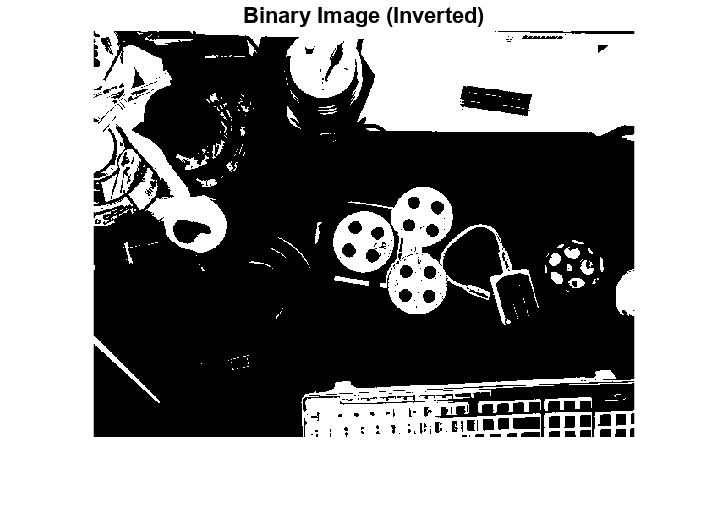


% 2. Convert to grayscale
grayImg = rgb2gray(img);

% 3. Threshold to get a binary image
%    We invert so dark regions become white in binImg.
level = 0.3;  % manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;  % invert => dark hub is bright/white in binImg

% 4. Show the inverted binary image
figure; imshow(binImg);
title('Binary Image (Inverted)');

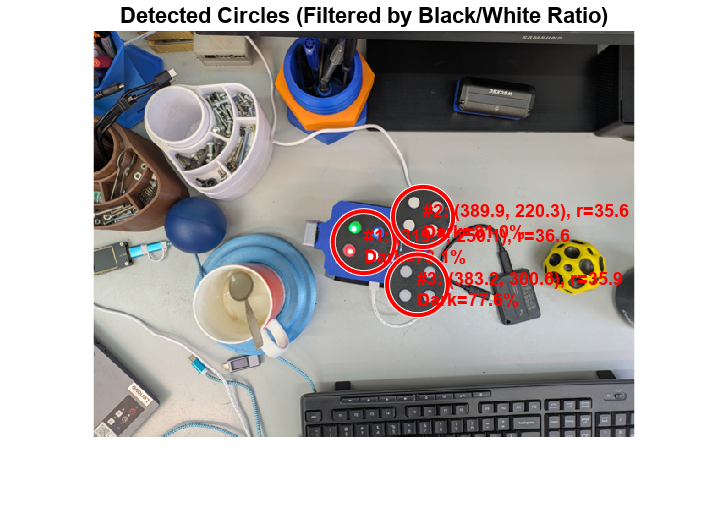

Circle 1 => Ctr=(319.7,250.1), R=36.6, Metric=0.810, DarkFr=0.78
Circle 2 => Ctr=(389.9,220.3), R=35.6, Metric=0.613, DarkFr=0.81


Circle 3 => Ctr=(383.2,300.6), R=35.9, Metric=0.490, DarkFr=0.78


Circle 4 => Filtered out (darkFraction=0.91)



% 5. Detect ALL circles 
%    The range [15 55] is an example; adjust as needed.
%    'ObjectPolarity','bright' because we inverted so that the hub is "bright."
[centers, radii, metric] = imfindcircles(binImg, [15 55], ...
    'ObjectPolarity','bright', 'Sensitivity',0.7);

% 6. Show original image and prepare for drawing
figure; imshow(img); hold on;
title('Detected Circles (Filtered by Black/White Ratio)');

% Initialize a mask image for the detected hubs.
hubMask = false(size(binImg));

if isempty(centers)
    fprintf('No circles found!\n');
    return;
end

% 7. For each circle, measure how much of it is "white" in binImg
for i = 1:length(radii)
    c = centers(i, :);   % [x, y] center
    r = radii(i);
    
    % Create a mask of pixels within this circle
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    distSq = (X - c(1)).^2 + (Y - c(2)).^2;
    circleMask = distSq <= (r^2);
    
    % Because in binImg a pixel value of 1 corresponds to a dark region in the original,
    % count how many pixels within the circle are 1.
    whiteCount = sum(binImg(circleMask), 'all');
    
    % Total pixel count in the circle mask:
    circleArea = sum(circleMask(:));
    
    % Calculate the fraction of the circle that is “dark” in the original image.
    darkFraction = whiteCount / circleArea;
    
    % Define a threshold: we keep circles whose darkFraction is between 70% and 85%.
    if darkFraction >= 0.70 && darkFraction <= 0.85
        % This circle meets the “darkness” criteria for a hub.
        viscircles(c, r, 'Color', 'r');  % draw the circle in red
        textStr = sprintf('#%d: (%.1f, %.1f), r=%.1f\nDark=%.1f%%', ...
            i, c(1), c(2), r, darkFraction*100);
        text(c(1), c(2)+5, textStr, ...
            'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
        
        fprintf('Circle %d => Ctr=(%.1f,%.1f), R=%.1f, Metric=%.3f, DarkFr=%.2f\n',...
            i, c(1), c(2), r, metric(i), darkFraction);
        
        % Accumulate the hub mask: set pixels inside the valid circle to true.
        hubMask(circleMask) = true;
    else
        fprintf('Circle %d => Filtered out (darkFraction=%.2f)\n', i, darkFraction);
    end
end

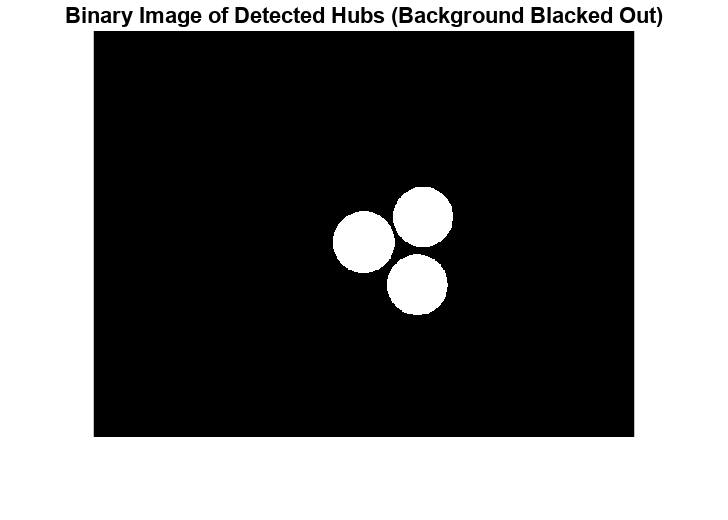


% 8. Display the binary image of detected hubs with the background blacked out.
figure; imshow(hubMask);
title('Binary Image of Detected Hubs (Background Blacked Out)');

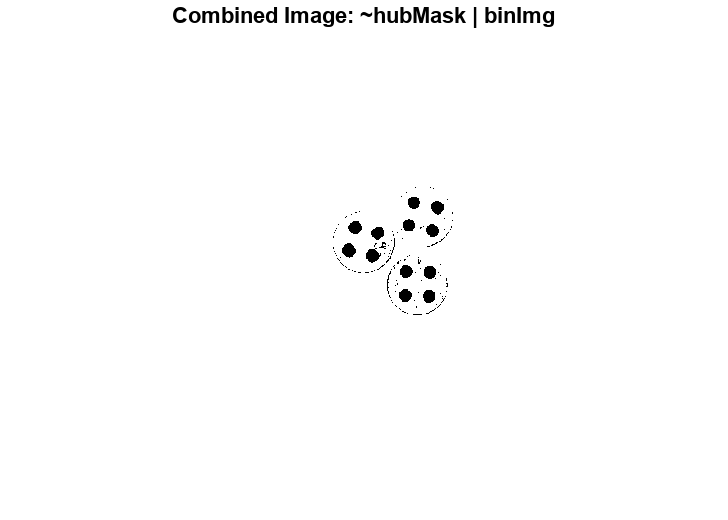


% --- After drawing the hubs and accumulating hubMask ---
% Create the combined image for blob detection:
% Outside hubs: ~hubMask is true, so combinedImage will be true.
% Inside hubs: combinedImage equals binImg (which has 0's where the LED areas are).
combinedImage = ~hubMask | binImg;

% (Optional) Display the combined image:
figure; imshow(combinedImage);
title('Combined Image: ~hubMask | binImg');


% Now, for each detected hub, count the black blobs (0's) of at least 10 pixels.
for i = 1:length(radii)
    c = centers(i, :);  % Hub center [x, y]
    r = radii(i);       % Hub radius
    
    % Create a binary mask for the current hub (circle)
    [X, Y] = meshgrid(1:size(combinedImage,2), 1:size(combinedImage,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Extract the part of the combined image corresponding to this hub.
    % Force all pixels outside the hub to white (logical 1) so they are ignored.
    hubSubImage = combinedImage;
    hubSubImage(~circleMask) = 1;
    
    % The black blobs inside the hub are the pixels with value 0.
    % Create a mask of these black pixels.
    blackRegion = (hubSubImage == 0);
    
    % Use 8-connected component analysis to detect blobs.
    CC = bwconncomp(blackRegion, 8);
    
    % Count only those blobs having at least 10 pixels.
    numBlobs = 0;
    for j = 1:CC.NumObjects
        if numel(CC.PixelIdxList{j}) >= 10
            numBlobs = numBlobs + 1;
        end
    end
    
    fprintf('Hub %d (center: [%.1f, %.1f], radius: %.1f): %d black blob(s) (>=10 pixels) detected.\n', ...
        i, c(1), c(2), r, numBlobs);
end

Hub 1 (center: [319.7, 250.1], radius: 36.6): 6 black blob(s) (>=10 pixels) detected.
Hub 2 (center: [389.9, 220.3], radius: 35.6): 5 black blob(s) (>=10 pixels) detected.
Hub 3 (center: [383.2, 300.6], radius: 35.9): 8 black blob(s) (>=10 pixels) detected.
Hub 4 (center: [271.3, 41.5], radius: 38.6): 0 black blob(s) (>=10 pixels) detected.


## 5. Detect Hubs and create a stracture of the hubs

%% 1. Resize image if larger than 720x480
[origH, origW, ~] = size(img);
maxW = 720;
maxH = 480;

if origW > maxW || origH > maxH
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

%% 2. Convert to grayscale
grayImg = rgb2gray(img);

%% 3. Threshold to get a binary image
%    We invert so dark regions become white in binImg.
level = 0.3;  % manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;  % invert: dark hub becomes white in binImg

%% 4. Show the inverted binary image
figure; imshow(binImg);
title('Binary Image (Inverted)');

Hub 1 => Center=(319.7,250.1), Radius=36.6, DarkFraction=0.78
Hub 2 => Center=(389.9,220.3), Radius=35.6, DarkFraction=0.81


Hub 3 => Center=(383.2,300.6), Radius=35.9, DarkFraction=0.78


Circle 4 filtered out (darkFraction=0.91)



%% 5. Detect ALL circles 
%    The range [15 55] is an example; adjust as needed.
%    'ObjectPolarity','bright' because we inverted so that the hub is "bright."
[centers, radii, metric] = imfindcircles(binImg, [15 55], ...
    'ObjectPolarity','bright', 'Sensitivity',0.7);

%% 6. Prepare for drawing and initialize hubMask and hubs structure
figure; imshow(img); hold on;
title('Detected Circles (Filtered by Black/White Ratio)');

% Create an empty mask for valid hubs.
hubMask = false(size(binImg));

% Initialize an empty structure array for hubs.
hubs = struct('center',{}, 'radius',{}, 'darkFraction',{}, 'numBlobs',{}, 'blobCentroids',{});
hubCount = 0;

%% 7. For each detected circle, compute the dark fraction and store valid hubs
for i = 1:length(radii)
    c = centers(i, :);   % [x, y] center
    r = radii(i);
    
    % Create a mask of pixels within this circle
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    circleMask = ( (X - c(1)).^2 + (Y - c(2)).^2 ) <= r^2;
    
    % Count pixels that are 1 in binImg (remember: 1 corresponds to the dark area in original)
    whiteCount = sum(binImg(circleMask), 'all');
    circleArea = sum(circleMask(:));
    
    % Fraction of circle that is “dark” in the original image.
    darkFraction = whiteCount / circleArea;
    
    % Define the acceptance criteria for a hub.
    if darkFraction >= 0.70 && darkFraction <= 0.85
        hubCount = hubCount + 1;
        
        % Store hub info in structure
        hubs(hubCount).center = c;
        hubs(hubCount).radius = r;
        hubs(hubCount).darkFraction = darkFraction;
        
        % Draw the circle and display text info
        viscircles(c, r, 'Color', 'r');
        text(c(1), c(2)+5, sprintf('#%d: (%.1f, %.1f), r=%.1f\nDark=%.1f%%', ...
            hubCount, c(1), c(2), r, darkFraction*100), ...
            'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
        
        fprintf('Hub %d => Center=(%.1f,%.1f), Radius=%.1f, DarkFraction=%.2f\n', ...
            hubCount, c(1), c(2), r, darkFraction);
        
        % Accumulate the hub mask
        hubMask(circleMask) = true;
    else
        fprintf('Circle %d filtered out (darkFraction=%.2f)\n', i, darkFraction);
    end
end


%% 8. Display the binary image of detected hubs (background blacked out)
figure; imshow(hubMask);
title('Binary Image of Detected Hubs (Background Blacked Out)');


%% 9. Create combined image for blob detection
% Outside hubs: ~hubMask is true, so combinedImage becomes white.
% Inside hubs: combinedImage equals binImg (which has 0's where the LED areas are).
combinedImage = ~hubMask | binImg;
figure; imshow(combinedImage);
title('Combined Image: ~hubMask | binImg');


%% 10. For each valid hub, count black blobs (>=100 pixels) and record blob centroids.
for i = 1:length(hubs)
    c = hubs(i).center;   % Hub center
    r = hubs(i).radius;    % Hub radius
    
    % Create a mask for the current hub
    [X, Y] = meshgrid(1:size(combinedImage,2), 1:size(combinedImage,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Extract only the current hub's area from the combined image.
    % Force pixels outside the hub to white so they do not interfere.
    hubSubImage = combinedImage;
    hubSubImage(~circleMask) = 1;
    
    % Black regions (0's) inside the hub correspond to LED blobs.
    blackRegion = (hubSubImage == 0);
    
    % Use 8-connected component analysis to detect blobs.
    CC = bwconncomp(blackRegion, 8);
    stats = regionprops(CC, 'Centroid', 'Area');
    
    % Filter out blobs with fewer than 100 pixels.
    validCentroids = [];
    for j = 1:length(stats)
        if stats(j).Area >= 100
            validCentroids = [validCentroids; stats(j).Centroid];  %#ok<AGROW>
        end
    end
    
    hubs(i).numBlobs = size(validCentroids, 1);
    hubs(i).blobCentroids = validCentroids;
    
    fprintf('Hub %d: %d black blob(s) detected inside.\n', i, hubs(i).numBlobs);
end

Hub 1: 4 black blob(s) detected inside.
Hub 2: 4 black blob(s) detected inside.
Hub 3: 4 black blob(s) detected inside.


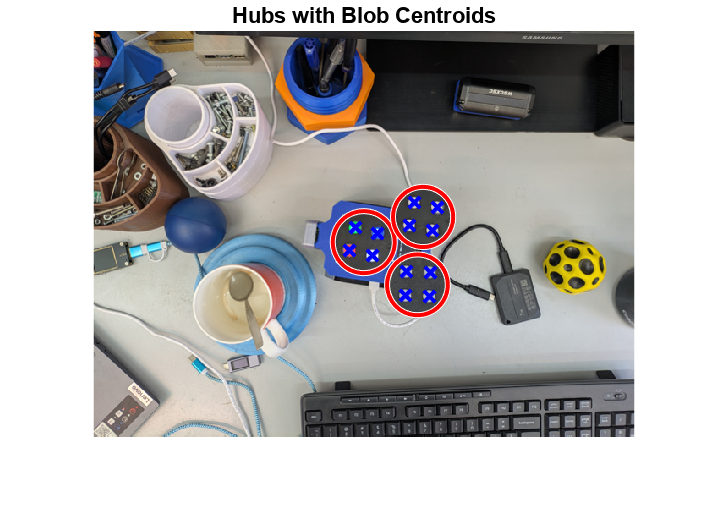


%% (Optional) Display hub blob centroids on original image
figure; imshow(img); hold on;
title('Hubs with Blob Centroids');
for i = 1:length(hubs)
    % Draw hub circle
    viscircles(hubs(i).center, hubs(i).radius, 'Color', 'r');
    % Mark blob centroids with blue crosses
    for j = 1:hubs(i).numBlobs
        plot(hubs(i).blobCentroids(j,1), hubs(i).blobCentroids(j,2), 'bx', 'LineWidth', 2, 'MarkerSize', 8);
    end
end

## Debug

%% Set debug variable (set to true to draw failed hubs with dashed lines)
DEBUG = true;

%% 1. Resize image if larger than 720x480
[origH, origW, ~] = size(img);
maxW = 720;
maxH = 480;
if origW > maxW || origH > maxH
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

%% 2. Convert to grayscale and threshold
grayImg = rgb2gray(img);
level = 0.3;  % Manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;  % Invert so that dark regions become white

figure; imshow(binImg);
title('Binary Image (Inverted)');

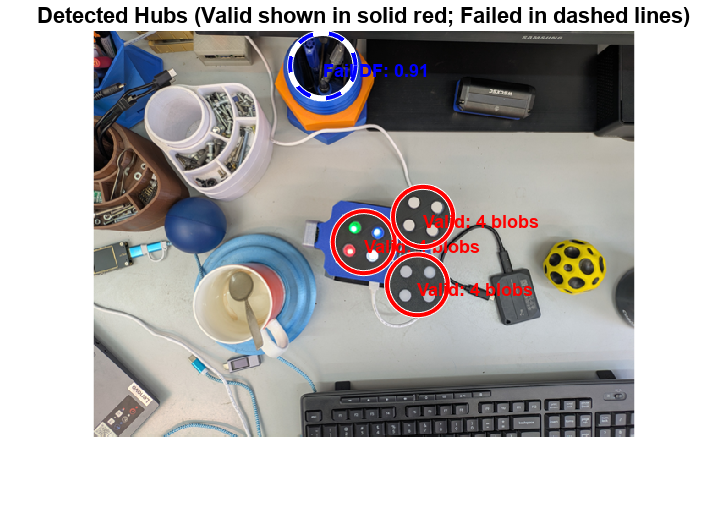

Valid Hub 1: Center=(319.7, 250.1), Radius=36.6, DarkFraction=0.78, 4 blobs detected.
Valid Hub 2: Center=(389.9, 220.3), Radius=35.6, DarkFraction=0.81, 4 blobs detected.
Valid Hub 3: Center=(383.2, 300.6), Radius=35.9, DarkFraction=0.78, 4 blobs detected.


Circle 4 filtered out: DarkFraction=0.91



%% 3. Detect circles (candidate hubs) using imfindcircles
% The range [15 55] is an example; adjust as needed.
% 'ObjectPolarity','bright' because we inverted the image so that the hub is bright.
[centers, radii, metric] = imfindcircles(binImg, [15 55], ...
    'ObjectPolarity','bright', 'Sensitivity',0.7);

%% 4. Prepare for drawing and initialize the structure for valid hubs
figure; imshow(img); hold on;
title('Detected Hubs (Valid shown in solid red; Failed in dashed lines)');

% Structure to store valid hubs (those that have 4 LED markers)
hubs = struct('center',{}, 'radius',{}, 'darkFraction',{}, 'numBlobs',{}, 'blobCentroids',{});
validHubCount = 0;

%% 5. Process each detected circle candidate
for i = 1:length(radii)
    c = centers(i, :);  % Candidate hub center [x, y]
    r = radii(i);       % Candidate hub radius
    
    % Create a circular mask for this candidate hub
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Compute dark-fraction: count white pixels in binImg (which represent dark areas originally)
    whiteCount = sum(binImg(circleMask), 'all');
    circleArea = sum(circleMask(:));
    darkFraction = whiteCount / circleArea;
    
    % Only consider candidate hubs with darkFraction between 70% and 85%
    if darkFraction >= 0.70 && darkFraction <= 0.85
        % --- LED Blob Detection within the candidate hub ---
        % Extract hub region from binImg: force pixels outside the hub to white
        hubSubImage = binImg;
        hubSubImage(~circleMask) = 1;
        
        % In the hub region, the LED markers (blobs) appear as black (0)
        blackRegion = (hubSubImage == 0);
        
        % Smooth the image to clean up noise using a morphological opening.
        se = strel('disk', 2);  % Adjust disk radius as needed
        blackRegionSmooth = imopen(blackRegion, se);
        
        % Detect connected components (8-connected) in the smoothed binary image.
        CC = bwconncomp(blackRegionSmooth, 8);
        stats = regionprops(CC, 'Centroid', 'Area');
        
        % Set minimum area threshold for blobs (e.g., 100 pixels)
        minBlobArea = 100;
        validCentroids = [];
        for j = 1:length(stats)
            if stats(j).Area >= minBlobArea
                validCentroids = [validCentroids; stats(j).Centroid]; %#ok<AGROW>
            end
        end
        numBlobs = size(validCentroids, 1);
        
        % --- Hub Validation ---
        % We require exactly 4 LED markers (blobs) inside the hub.
        if numBlobs == 4
            % This candidate hub is valid. Store its data.
            validHubCount = validHubCount + 1;
            hubs(validHubCount).center = c;
            hubs(validHubCount).radius = r;
            hubs(validHubCount).darkFraction = darkFraction;
            hubs(validHubCount).numBlobs = numBlobs;
            hubs(validHubCount).blobCentroids = validCentroids;
            
            % Draw the valid hub with a solid red circle.
            viscircles(c, r, 'Color', 'r');
            text(c(1), c(2)+5, 'Valid: 4 blobs', 'Color', 'r', ...
                'FontWeight', 'bold', 'FontSize', 9);
            fprintf('Valid Hub %d: Center=(%.1f, %.1f), Radius=%.1f, DarkFraction=%.2f, 4 blobs detected.\n', ...
                validHubCount, c(1), c(2), r, darkFraction);
        else
            % The candidate hub passed dark-fraction criteria but does not have 4 blobs.
            if DEBUG
                % Draw the candidate hub with a dashed green circle.
                viscircles(c, r, 'Color', 'g', 'LineStyle', '--');
                text(c(1), c(2)+5, sprintf('Fail: %d blobs', numBlobs), ...
                    'Color', 'g', 'FontWeight', 'bold', 'FontSize', 9);
            end
            fprintf('Candidate hub at (%.1f, %.1f) with radius=%.1f failed: %d blobs detected (DarkFraction=%.2f).\n', ...
                c(1), c(2), r, numBlobs, darkFraction);
        end
    else
        % The candidate hub does not meet the dark-fraction criteria.
        if DEBUG
            % Draw the failed candidate with a dashed blue circle.
            viscircles(c, r, 'Color', 'b', 'LineStyle', '--');
            text(c(1), c(2)+5, sprintf('Fail DF: %.2f', darkFraction), ...
                'Color', 'b', 'FontWeight', 'bold', 'FontSize', 9);
        end
        fprintf('Circle %d filtered out: DarkFraction=%.2f\n', i, darkFraction);
    end
end


%% 6. (Optional) Display the structure of valid hubs
disp('Valid hubs detected:');

Valid hubs detected:


disp(hubs);

  1×3 struct array with fields:

    center
    radius
    darkFraction
    numBlobs
    blobCentroids



## Color detection

%% Set debug variable (set to true to draw failed hubs with dashed lines)
DEBUG = true;

%% 1. Resize image if larger than 720x480
[origH, origW, ~] = size(img);
maxW = 720;
maxH = 480;
if origW > maxW || origH > maxH
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

%% 2. Convert to grayscale and threshold
grayImg = rgb2gray(img);
level = 0.3;  % Manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;  % Invert so that dark areas become white

figure; imshow(binImg);
title('Binary Image (Inverted)');

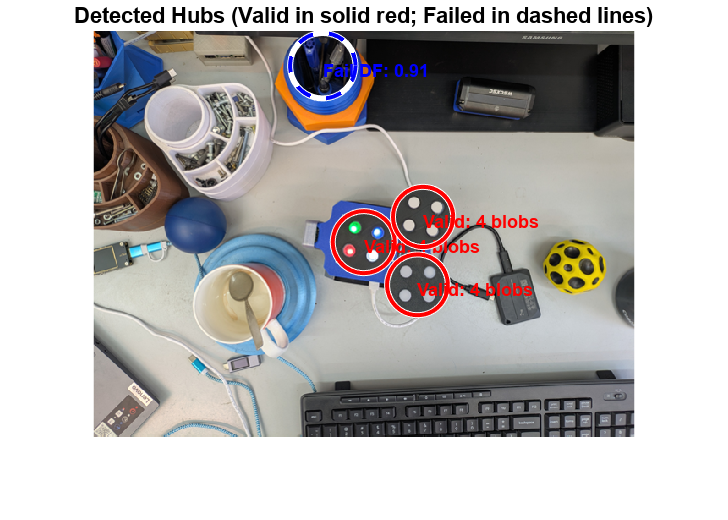

Valid Hub 1: Center=(319.7, 250.1), Radius=36.6, DarkFraction=0.78, 4 blobs detected.
Valid Hub 2: Center=(389.9, 220.3), Radius=35.6, DarkFraction=0.81, 4 blobs detected.
Valid Hub 3: Center=(383.2, 300.6), Radius=35.9, DarkFraction=0.78, 4 blobs detected.


Circle 4 filtered out: DarkFraction=0.91



%% 3. Detect circles (candidate hubs) using imfindcircles
% The range [15 55] is an example; adjust as needed.
% 'ObjectPolarity','bright' because we inverted the image so that the hub is bright.
[centers, radii, metric] = imfindcircles(binImg, [15 55], ...
    'ObjectPolarity','bright', 'Sensitivity',0.7);

%% 4. Prepare for drawing and initialize structure for valid hubs
figure; imshow(img); hold on;
title('Detected Hubs (Valid in solid red; Failed in dashed lines)');

% Initialize structure to store valid hubs.
hubs = struct('center',{}, 'radius',{}, 'darkFraction',{}, ...
    'numBlobs',{}, 'blobCentroids',{}, 'blobColors',{});
validHubCount = 0;

%% 5. Process each candidate hub
for i = 1:length(radii)
    c = centers(i, :);  % Candidate hub center [x, y]
    r = radii(i);       % Candidate hub radius
    
    % Create a circular mask for this candidate hub.
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Compute darkFraction: count white pixels in binImg (which represent dark areas in the original)
    whiteCount = sum(binImg(circleMask), 'all');
    circleArea = sum(circleMask(:));
    darkFraction = whiteCount / circleArea;
    
    % Only consider candidate hubs with darkFraction between 70% and 85%.
    if darkFraction >= 0.70 && darkFraction <= 0.85
        % --- LED Blob Detection within the candidate hub ---
        % Extract hub region from binImg by forcing pixels outside the hub to white.
        hubSubImage = binImg;
        hubSubImage(~circleMask) = 1;
        
        % In the hub region, the LED markers appear as black (0).
        blackRegion = (hubSubImage == 0);
        
        % Smooth the image to clean noise using a morphological opening.
        se = strel('disk', 2);  % Adjust disk radius as needed.
        blackRegionSmooth = imopen(blackRegion, se);
        
        % Detect connected components (8-connected) in the smoothed image.
        CC = bwconncomp(blackRegionSmooth, 8);
        stats = regionprops(CC, 'Centroid', 'Area');
        
        % Set minimum blob area (in pixels); adjust if needed.
        minBlobArea = 100;
        validCentroids = [];
        validColors = {};  % To store the color of each blob.
        colorThreshold = 30;  % Threshold for deciding if colors are similar (for white)
        
        % Process each detected blob.
        for j = 1:length(stats)
            if stats(j).Area >= minBlobArea
                % Save the centroid.
                validCentroids = [validCentroids; stats(j).Centroid]; %#ok<AGROW>
                
                % Retrieve the pixel indices for this blob.
                blobIndices = CC.PixelIdxList{j};
                
                % Compute the mean R, G, B values from the original color image.
                R_channel = img(:,:,1);
                G_channel = img(:,:,2);
                B_channel = img(:,:,3);
                meanR = mean(double(R_channel(blobIndices)));
                meanG = mean(double(G_channel(blobIndices)));
                meanB = mean(double(B_channel(blobIndices)));
                
                % Classify the blob color.
                if abs(meanR - meanG) < colorThreshold && abs(meanR - meanB) < colorThreshold && abs(meanG - meanB) < colorThreshold
                    blobColor = 'white';
                elseif meanR > meanG && meanR > meanB
                    blobColor = 'red';
                elseif meanG > meanR && meanG > meanB
                    blobColor = 'green';
                elseif meanB > meanR && meanB > meanG
                    blobColor = 'blue';
                else
                    blobColor = 'unknown';
                end
                
                validColors{end+1} = blobColor;  %#ok<AGROW>
            end
        end
        
        numBlobs = size(validCentroids, 1);
        
        % --- Hub Validation ---
        % We require exactly 4 LED markers (blobs) inside the hub.
        if numBlobs == 4
            validHubCount = validHubCount + 1;
            hubs(validHubCount).center = c;
            hubs(validHubCount).radius = r;
            hubs(validHubCount).darkFraction = darkFraction;
            hubs(validHubCount).numBlobs = numBlobs;
            hubs(validHubCount).blobCentroids = validCentroids;
            hubs(validHubCount).blobColors = validColors;
            
            % Draw the valid hub with a solid red circle.
            viscircles(c, r, 'Color', 'r');
            text(c(1), c(2)+5, 'Valid: 4 blobs', 'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
            fprintf('Valid Hub %d: Center=(%.1f, %.1f), Radius=%.1f, DarkFraction=%.2f, 4 blobs detected.\n', ...
                validHubCount, c(1), c(2), r, darkFraction);
        else
            % Candidate hub passed darkFraction but does not have exactly 4 blobs.
            if DEBUG
                viscircles(c, r, 'Color', 'g', 'LineStyle', '--');
                text(c(1), c(2)+5, sprintf('Fail: %d blobs', numBlobs), 'Color', 'g', 'FontWeight', 'bold', 'FontSize', 9);
            end
            fprintf('Candidate hub at (%.1f, %.1f) with radius=%.1f failed: %d blobs detected (DarkFraction=%.2f).\n', ...
                c(1), c(2), r, numBlobs, darkFraction);
        end
    else
        % Candidate hub does not meet darkFraction criteria.
        if DEBUG
            viscircles(c, r, 'Color', 'b', 'LineStyle', '--');
            text(c(1), c(2)+5, sprintf('Fail DF: %.2f', darkFraction), 'Color', 'b', 'FontWeight', 'bold', 'FontSize', 9);
        end
        fprintf('Circle %d filtered out: DarkFraction=%.2f\n', i, darkFraction);
    end
end


%% 6. (Optional) Display the structure of valid hubs
disp('Valid hubs detected:');

Valid hubs detected:


disp(hubs);

  1×3 struct array with fields:

    center
    radius
    darkFraction
    numBlobs
    blobCentroids
    blobColors



## stracture with clockwise blob numbering

%% Set debug variable (set to true to draw failed hubs with dashed lines)
DEBUG = true;

%% 1. Resize image if larger than 720x480
[origH, origW, ~] = size(img);
maxW = 720;
maxH = 480;
if origW > maxW || origH > maxH
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

%% 2. Convert to grayscale and threshold
grayImg = rgb2gray(img);
level = 0.3;  % Manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;  % Invert so that dark areas become white

figure; imshow(binImg);
title('Binary Image (Inverted)');

Valid Hub 1: Center=(319.7, 250.1), Radius=36.6, DarkFraction=0.78, 4 blobs detected.
Valid Hub 2: Center=(389.9, 220.3), Radius=35.6, DarkFraction=0.81, 4 blobs detected.
Valid Hub 3: Center=(383.2, 300.6), Radius=35.9, DarkFraction=0.78, 4 blobs detected.


Circle 4 filtered out: DarkFraction=0.91



%% 3. Detect circles (candidate hubs) using imfindcircles
% The range [15 55] is an example; adjust as needed.
% 'ObjectPolarity','bright' because we inverted the image so that the hub is bright.
[centers, radii, metric] = imfindcircles(binImg, [15 55], ...
    'ObjectPolarity','bright', 'Sensitivity',0.7);

%% 4. Prepare for drawing and initialize structure for valid hubs
figure; imshow(img); hold on;
title('Detected Hubs (Valid in solid red; Failed in dashed lines)');

% Initialize structure to store valid hubs.
hubs = struct('center',{}, 'radius',{}, 'numBlobs',{}, 'darkFraction',{}, ...
    'blob1',{}, 'blob2',{}, 'blob3',{}, 'blob4',{});
validHubCount = 0;

%% 5. Process each candidate hub
for i = 1:length(radii)
    c = centers(i, :);  % Candidate hub center [x, y]
    r = radii(i);       % Candidate hub radius
    
    % Create a circular mask for this candidate hub.
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Compute darkFraction: count white pixels in binImg (which represent dark areas originally)
    whiteCount = sum(binImg(circleMask), 'all');
    circleArea = sum(circleMask(:));
    darkFraction = whiteCount / circleArea;
    
    % Only consider candidate hubs with darkFraction between 70% and 85%.
    if darkFraction >= 0.70 && darkFraction <= 0.85
        % --- LED Blob Detection within the candidate hub ---
        % Extract hub region from binImg: force pixels outside the hub to white.
        hubSubImage = binImg;
        hubSubImage(~circleMask) = 1;
        
        % In the hub region, the LED markers appear as black (0).
        blackRegion = (hubSubImage == 0);
        
        % Smooth the image to clean noise using a morphological opening.
        se = strel('disk', 2);  % Adjust disk radius as needed.
        blackRegionSmooth = imopen(blackRegion, se);
        
        % Detect connected components (8-connected) in the smoothed image.
        CC = bwconncomp(blackRegionSmooth, 8);
        stats = regionprops(CC, 'Centroid', 'Area');
        
        % Set minimum blob area (in pixels); adjust if needed.
        minBlobArea = 100;
        validCentroids = [];
        validColors = {};  % To store the color of each blob.
        colorThreshold = 30;  % Threshold for deciding if colors are similar (for white)
        
        % Process each detected blob.
        for j = 1:length(stats)
            if stats(j).Area >= minBlobArea
                % Save the centroid.
                validCentroids = [validCentroids; stats(j).Centroid]; %#ok<AGROW>
                
                % Retrieve the pixel indices for this blob.
                blobIndices = CC.PixelIdxList{j};
                
                % Compute the mean R, G, B values from the original color image.
                R_channel = img(:,:,1);
                G_channel = img(:,:,2);
                B_channel = img(:,:,3);
                meanR = mean(double(R_channel(blobIndices)));
                meanG = mean(double(G_channel(blobIndices)));
                meanB = mean(double(B_channel(blobIndices)));
                
                % Classify the blob color.
                if abs(meanR - meanG) < colorThreshold && abs(meanR - meanB) < colorThreshold && abs(meanG - meanB) < colorThreshold
                    blobColor = 'white';
                elseif meanR > meanG && meanR > meanB
                    blobColor = 'red';
                elseif meanG > meanR && meanG > meanB
                    blobColor = 'green';
                elseif meanB > meanR && meanB > meanG
                    blobColor = 'blue';
                else
                    blobColor = 'unknown';
                end
                
                validColors{end+1} = blobColor;  %#ok<AGROW>
            end
        end
        
        numBlobs = size(validCentroids, 1);
        
        % --- Hub Validation ---
        % We require exactly 4 LED markers (blobs) inside the hub.
        if numBlobs == 4
            % --- Sort the 4 blobs in clockwise order ---
            % We define "up" (negative y direction) as 0°.
            angles = zeros(numBlobs, 1);
            for k = 1:numBlobs
                dX = validCentroids(k,1) - c(1);
                dY = validCentroids(k,2) - c(2);
                % Compute angle relative to upward direction.
                angles(k) = mod(atan2(dX, -dY), 2*pi);
            end
            [~, sortOrder] = sort(angles);
            sortedCentroids = validCentroids(sortOrder, :);
            sortedColors = validColors(sortOrder);
            
            % Store the valid hub in the structure.
            validHubCount = validHubCount + 1;
            hubs(validHubCount).center = c;
            hubs(validHubCount).radius = r;
            hubs(validHubCount).numBlobs = numBlobs;
            hubs(validHubCount).darkFraction = darkFraction;
            
            % Now assign each blob to a sub-structure (blob1, blob2, blob3, blob4)
            for k = 1:numBlobs
                fieldName = sprintf('blob%d', k);
                hubs(validHubCount).(fieldName).center = sortedCentroids(k, :);
                hubs(validHubCount).(fieldName).color = sortedColors{k};
            end
            
            % Draw the valid hub with a solid red circle.
            viscircles(c, r, 'Color', 'r');
            text(c(1), c(2)+5, 'Valid: 4 blobs', 'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
            fprintf('Valid Hub %d: Center=(%.1f, %.1f), Radius=%.1f, DarkFraction=%.2f, 4 blobs detected.\n', ...
                validHubCount, c(1), c(2), r, darkFraction);
        else
            % Candidate hub passed darkFraction but does not have exactly 4 blobs.
            if DEBUG
                viscircles(c, r, 'Color', 'g', 'LineStyle', '--');
                text(c(1), c(2)+5, sprintf('Fail: %d blobs', numBlobs), 'Color', 'g', 'FontWeight', 'bold', 'FontSize', 9);
            end
            fprintf('Candidate hub at (%.1f, %.1f) with radius=%.1f failed: %d blobs detected (DarkFraction=%.2f).\n', ...
                c(1), c(2), r, numBlobs, darkFraction);
        end
    else
        % Candidate hub does not meet darkFraction criteria.
        if DEBUG
            viscircles(c, r, 'Color', 'b', 'LineStyle', '--');
            text(c(1), c(2)+5, sprintf('Fail DF: %.2f', darkFraction), 'Color', 'b', 'FontWeight', 'bold', 'FontSize', 9);
        end
        fprintf('Circle %d filtered out: DarkFraction=%.2f\n', i, darkFraction);
    end
end


%% 6. (Optional) Display the structure of valid hubs
disp('Valid hubs detected:');

Valid hubs detected:


disp(hubs);

  1×3 struct array with fields:

    center
    radius
    numBlobs
    darkFraction
    blob1
    blob2
    blob3
    blob4



## Refined Code

%% Set debug variable (set to true to mark failed hubs with dashed red)
DEBUG = true;

%% 1. Resize image if larger than 720x480
[origH, origW, ~] = size(img);
maxW = 720;
maxH = 480;
if origW > maxW || origH > maxH
    scale = min(maxW/origW, maxH/origH);
    img = imresize(img, scale);
    fprintf('Image resized from (%d, %d) to (%d, %d)\n', ...
        origH, origW, size(img,1), size(img,2));
end

%% 2. Convert to grayscale and threshold
grayImg = rgb2gray(img);
level = 0.3;  % Manual threshold (tweak as needed)
binImg = imbinarize(grayImg, level);
binImg = ~binImg;  % Invert so that dark areas become white

figure; imshow(binImg);
title('Binary Image (Inverted)');

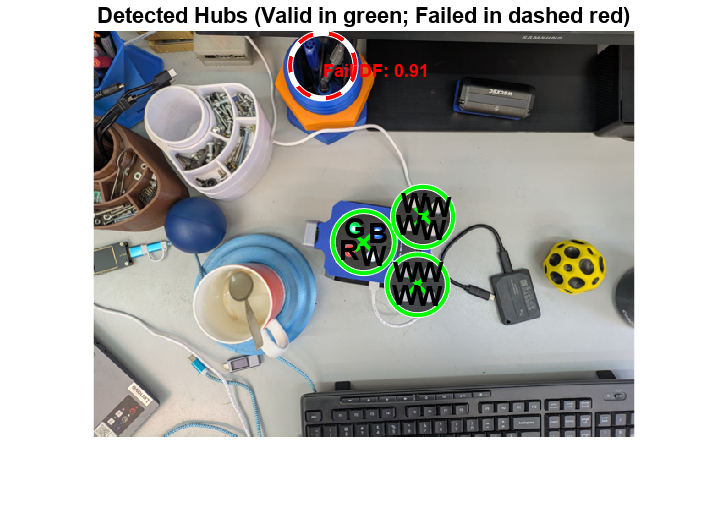

Valid Hub 1: Center=(319.7, 250.1), Radius=36.6, DarkFraction=0.78, 4 blobs detected.
Valid Hub 2: Center=(389.9, 220.3), Radius=35.6, DarkFraction=0.81, 4 blobs detected.
Valid Hub 3: Center=(383.2, 300.6), Radius=35.9, DarkFraction=0.78, 4 blobs detected.


Circle 4 filtered out: DarkFraction=0.91



%% 3. Detect circles (candidate hubs) using imfindcircles
% The range [15 55] is an example; adjust as needed.
% 'ObjectPolarity','bright' because we inverted the image so that the hub appears bright.
[centers, radii, metric] = imfindcircles(binImg, [15 55], ...
    'ObjectPolarity','bright', 'Sensitivity',0.7);

%% 4. Prepare for drawing and initialize structure for valid hubs
figure; imshow(img); hold on;
title('Detected Hubs (Valid in green; Failed in dashed red)');

% Initialize structure to store valid hubs.
% Each valid hub will have:
%   hub.center, hub.radius, hub.numBlobs, hub.darkFraction,
%   hub.blob1.center, hub.blob1.color, ... up to blob4.
hubs = struct('center',{}, 'radius',{}, 'numBlobs',{}, 'darkFraction',{}, ...
    'blob1',{}, 'blob2',{}, 'blob3',{}, 'blob4',{});
validHubCount = 0;

%% 5. Process each candidate hub
for i = 1:length(radii)
    c = centers(i, :);  % Candidate hub center [x, y]
    r = radii(i);       % Candidate hub radius
    
    % Create a circular mask for this candidate hub.
    [X, Y] = meshgrid(1:size(binImg,2), 1:size(binImg,1));
    circleMask = ((X - c(1)).^2 + (Y - c(2)).^2) <= r^2;
    
    % Compute darkFraction: count white pixels in binImg (which represent dark areas originally)
    whiteCount = sum(binImg(circleMask), 'all');
    circleArea = sum(circleMask(:));
    darkFraction = whiteCount / circleArea;
    
    if darkFraction >= 0.70 && darkFraction <= 0.85
        % --- LED Blob Detection within the candidate hub ---
        % Force pixels outside the hub to white.
        hubSubImage = binImg;
        hubSubImage(~circleMask) = 1;
        
        % In the hub region, LED markers appear as black (0).
        blackRegion = (hubSubImage == 0);
        
        % Smooth the image to remove noise (morphological opening).
        se = strel('disk', 2);  % Adjust disk radius as needed.
        blackRegionSmooth = imopen(blackRegion, se);
        
        % Detect connected components (8-connected) in the smoothed image.
        CC = bwconncomp(blackRegionSmooth, 8);
        stats = regionprops(CC, 'Centroid', 'Area');
        
        % Set minimum blob area (in pixels); adjust if needed.
        minBlobArea = 100;
        validCentroids = [];
        validColors = {};  % To store the color of each blob.
        colorThreshold = 30;  % Threshold to decide if colors are similar (for white)
        
        % Process each detected blob.
        for j = 1:length(stats)
            if stats(j).Area >= minBlobArea
                % Save the centroid.
                validCentroids = [validCentroids; stats(j).Centroid]; %#ok<AGROW>
                
                % Retrieve the pixel indices for this blob.
                blobIndices = CC.PixelIdxList{j};
                
                % Compute the mean R, G, B values from the original color image.
                R_channel = img(:,:,1);
                G_channel = img(:,:,2);
                B_channel = img(:,:,3);
                meanR = mean(double(R_channel(blobIndices)));
                meanG = mean(double(G_channel(blobIndices)));
                meanB = mean(double(B_channel(blobIndices)));
                
                % Classify the blob color.
                if abs(meanR - meanG) < colorThreshold && abs(meanR - meanB) < colorThreshold && abs(meanG - meanB) < colorThreshold
                    blobColor = 'white';
                elseif meanR > meanG && meanR > meanB
                    blobColor = 'red';
                elseif meanG > meanR && meanG > meanB
                    blobColor = 'green';
                elseif meanB > meanR && meanB > meanG
                    blobColor = 'blue';
                else
                    blobColor = 'unknown';
                end
                
                validColors{end+1} = blobColor;  %#ok<AGROW>
            end
        end
        
        numBlobs = size(validCentroids, 1);
        
        % --- Hub Validation ---
        % We require exactly 4 LED markers (blobs) inside the hub.
        if numBlobs == 4
            % --- Sort the 4 blobs in clockwise order ---
            % Define "up" (negative y) as 0°.
            angles = zeros(numBlobs, 1);
            for k = 1:numBlobs
                dX = validCentroids(k,1) - c(1);
                dY = validCentroids(k,2) - c(2);
                % Angle relative to upward direction; use mod to get 0 to 2*pi.
                angles(k) = mod(atan2(dX, -dY), 2*pi);
            end
            [~, sortOrder] = sort(angles);
            sortedCentroids = validCentroids(sortOrder, :);
            sortedColors = validColors(sortOrder);
            
            % Store the valid hub in the structure.
            validHubCount = validHubCount + 1;
            hubs(validHubCount).center = c;
            hubs(validHubCount).radius = r;
            hubs(validHubCount).numBlobs = numBlobs;
            hubs(validHubCount).darkFraction = darkFraction;
            for k = 1:numBlobs
                fieldName = sprintf('blob%d', k);
                hubs(validHubCount).(fieldName).center = sortedCentroids(k, :);
                hubs(validHubCount).(fieldName).color = sortedColors{k};
            end
            
            % --- Draw Valid Hub ---
            % Draw a solid green circle around the hub.
            viscircles(c, r, 'Color', 'g');
            % Mark the hub center with a green X.
            plot(c(1), c(2), 'gx', 'MarkerSize', 12, 'LineWidth', 2);
            
            % For each blob, annotate its first letter (R, G, B, W).
            for k = 1:numBlobs
                blobLetter = upper(sortedColors{k}(1));  % Take the first letter and convert to uppercase.
                blobPos = sortedCentroids(k, :);
                text(blobPos(1), blobPos(2), blobLetter, 'Color', 'k', ...
                    'FontSize', 14, 'FontWeight', 'bold', 'HorizontalAlignment','center');
            end
            
            fprintf('Valid Hub %d: Center=(%.1f, %.1f), Radius=%.1f, DarkFraction=%.2f, 4 blobs detected.\n', ...
                validHubCount, c(1), c(2), r, darkFraction);
        else
            % Candidate hub passed darkFraction but does not have exactly 4 blobs.
            if DEBUG
                viscircles(c, r, 'Color', 'r', 'LineStyle', '--');
                text(c(1), c(2)+5, sprintf('Fail: %d blobs', numBlobs), ...
                    'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
            end
            fprintf('Candidate hub at (%.1f, %.1f) with radius=%.1f failed: %d blobs detected (DarkFraction=%.2f).\n', ...
                c(1), c(2), r, numBlobs, darkFraction);
        end
    else
        % Candidate hub does not meet darkFraction criteria.
        if DEBUG
            viscircles(c, r, 'Color', 'r', 'LineStyle', '--');
            text(c(1), c(2)+5, sprintf('Fail DF: %.2f', darkFraction), ...
                'Color', 'r', 'FontWeight', 'bold', 'FontSize', 9);
        end
        fprintf('Circle %d filtered out: DarkFraction=%.2f\n', i, darkFraction);
    end
end


%% 6. (Optional) Display the structure of valid hubs
disp('Valid hubs detected:');

Valid hubs detected:


disp(hubs);

  1×3 struct array with fields:

    center
    radius
    numBlobs
    darkFraction
    blob1
    blob2
    blob3
    blob4

